clear
clc
close all

% Define attractors of the network
T = [1 1; -1 -1; 1 -1]'; 

n = 100;
r_values = [-1,-0.7,-0.5,-0.2,0.1, 0.6, 1]; % Define multiple values of r
idx = 1;

frames = cell(numel(r_values), 1); % Create a cell array to store the frames

for i = 1:numel(r_values)
    idx = 1;
    r = r_values(i); % Get the current value of r
    
    points = zeros(n, 2); % pre-allocate an n-by-2 matrix to store the points
    theta_increment = 2*pi/n; % calculate the angle increment

    for j = 1:n
        theta = j*theta_increment; % calculate the angle for this point
        x = r*cos(theta); % calculate the x-coordinate
        y = r*sin(theta); % calculate the y-coordinate
        if abs(x) ~= 1 && abs(y) ~= 1 && abs(x) ~=  0.5 && abs(y) ~= 0.5 && abs(x) ~=  0.7 && abs(y) ~= 0.7 && abs(x) ~=  0.2 && abs(y) ~= 0.2 && abs(x) ~=  0.1 && abs(y) ~= 0.1 && abs(x) ~=  0.6 && abs(y) ~= 0.6
            points(idx,:) = [x, y]; % store the point in the points matrix
            idx = idx + 1;
        end

    end
    points = points(1:idx-1, :);
    frames{i} = points; % Save the points for this value of r in the cell array
end

selected_points = zeros(50, 2); % Pre-allocate the selected points array
total_points = 96 * 4; % Total number of points in the frame
indices = randperm(total_points, 50);
for i = 1:numel(indices)
    cell_idx = ceil(indices(i) / 96); % Get the cell index
    point_idx = mod(indices(i), 96); % Get the point index within the cell
    
    if point_idx == 0
        point_idx = 96;
    end
    
    selected_points(i, :) = frames{cell_idx}(point_idx, :);
end

% Initialise network
net = newhop(T);

% Run network with set of initial states

%Ai和100个Y一一对应，形成evolution

for i=1:30
    i
    for e=1:length(selected_points)
        a = [selected_points(e,1),selected_points(e,2)]';
        y = net({50}, {}, a);
        record = [a cell2mat(y)];
        plot(selected_points(e,1),selected_points(e,2),'bx',record(1,:),record(2,:),'r');
        hold on;
        plot(record(1,50),record(2,50),'gO');
    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

legend('initial state','time evolution','attractor','Location', 'northeast');
title('Time evolution in the phase space of 2d Hopfield model');
hold off



Y= net({50}, {}, points');

% Find the set of final states
final_states = cell2mat(Y(1,50));

% plot(final_states)
unique_states = unique(final_states','rows');




% Calculate average number of iterations until convergence
percent_converged = zeros(1,20);

for i=1:30

    num_converged = 0;
    Y = net({i}, {}, points');
    final_states = cell2mat(Y(1,i))';
    
    for j=1:length(final_states)
        is_converged = ismember(final_states(j,:),unique_states,'rows');
        num_converged = num_converged + is_converged;
    end
    percent_converged(i) = num_converged/length(final_states);
    if percent_converged(i) == 1

        break
        
    end
end
i

i = 19


percent_converged;




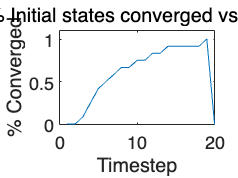


hold off
plot(percent_converged);
title("% Initial states converged vs Time");
ylim([0 1.1]);
xlabel("Timestep");
ylabel("% Converged");

% 2D
% data generation: 50 data points 
% 4 attractors, why 4 not 3
% convergence iteration: 19


clear
clc
close all

% Define attractors of the network
T = [1 1 1; -1 -1 1; 1 -1 -1]';
r_values = [-1, -0.7, -0.5, -0.2, 0.1, 0.6, 1]; % Define multiple values of r
idx = 1;
% Make initial states on a globe
n = 50;

points = zeros(n, 3); % pre-allocate an n-by-3 matrix to store the points
phi_increment = pi/(n+1); % calculate the angle increment for phi
theta_increment = 2*pi/n; % calculate the angle increment for theta
for i = 1:n
    phi = i*phi_increment; % calculate the angle for phi
    theta = i*theta_increment; % calculate the angle for theta
    r = -1 + 2 * rand(); % set the radial distance to 1 to ensure the points lie within the [-1,1] range
    x = r*cos(theta)*sin(phi); % calculate the x-coordinate
    y = r*sin(theta)*sin(phi); % calculate the y-coordinate
    z = r*cos(phi); % calculate the z-coordinate
    points(i,:) = [x, y, z]; % store the point in the points matrix
end


net = newhop(T);

% Run network with set of initial states

%Ai和100个Y一一对应，形成evolution

for i=1:50
    i
    for e=1:length(points)
        a = [points(e,1),points(e,2),points(e,3)]';
        Y = net({200}, {}, a);
        record = [a cell2mat(Y)];
        plot3(points(e,1),points(e,2),points(e,3),'bx',record(1,:),record(2,:),record(3,:),'r');
        hold on;
        plot3(record(1,200),record(2,200),record(3,200),'gO');
    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

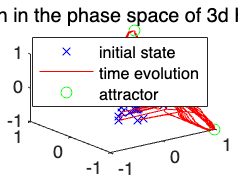

legend('initial state','time evolution','attractor','Location', 'northeast');
title('Time evolution in the phase space of 3d Hopfield model');
hold off

% Initialise network
net = newhop(T);

% Run network with set of initial states
Y = net({200}, {}, points');

% Find the set of final states
final_states = cell2mat(Y(1,200))';
rounded_final_states = round(final_states, 4);

unique_states = unique(final_states,'rows')

unique_states =     -1    -1     1
     1    -1    -1
     1     1     1


rounded_unique_states = unique(rounded_final_states,'rows')

rounded_unique_states =     -1    -1     1
     1    -1    -1
     1     1     1


% Calculate average number of iterations until convergence
percent_converged = zeros(1,100);

for i=1:100
    num_converged = 0;
    Y = net({i}, {}, points');
    final_states = cell2mat(Y(1,i))';
    for j=1:length(final_states)
        is_converged = ismember(final_states(j,:),rounded_unique_states,'rows');
        num_converged = num_converged + is_converged;
    end
    percent_converged(i) = num_converged/length(final_states);
end

percent_converged

percent_converged =          0         0         0         0    0.0200    0.0400    0.0800    0.1000    0.1000    0.1600    0.2200    0.3400    0.3800    0.4200    0.5200    0.5600    0.5600    0.6200    0.6800    0.7200    0.7400    0.7600    0.8000    0.8000    0.8200    0.8600    0.8600    0.8600    0.8600    0.8800    0.8800    0.9000    0.9000    0.9200    0.9200    0.9200    0.9200    0.9600    0.9600    0.9800    0.9800    0.9800    0.9800    0.9800    0.9800    1.0000    1.0000    1.0000    1.0000    1.0000


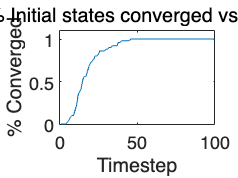

plot(percent_converged)
title("% Initial states converged vs Time");
ylim([0 1.1]);
xlabel("Timestep");
ylabel("% Converged");

% converge iteration: 46

% Overlapping attractors: If the attractors in the network are not perfectly orthogonal or independent, they can overlap in the state space. This overlap can lead to the emergence of new attractors that are combinations or superpositions of the original attractors. These new attractors may not be desired or intended but can still arise due to the network's non-linear dynamics.
% 
% Insufficient training or learning: The weights of a Hopfield network are typically learned using a Hebbian learning rule, where the weights are updated based on the correlation between the desired attractors. If the training process is not thorough or if there is insufficient training data, the learned weights may not accurately capture the desired attractors, leading to the emergence of unwanted attractors.
% 
% Noise or perturbations: The presence of noise or external perturbations in the network can disrupt the convergence to the desired attractors and introduce additional attractors. These additional attractors can arise due to the amplification or propagation of the noise through the network dynamics.
% 
% Network architecture or parameters: The architecture and parameters of the Hopfield network, such as the number of neurons, connectivity pattern, or the choice of activation function, can also influence the emergence of unwanted attractors. Inappropriate settings of these parameters can lead to unintended dynamics and attractor landscapes.
